## Модель канала по Шеннону

Пункт 1. 

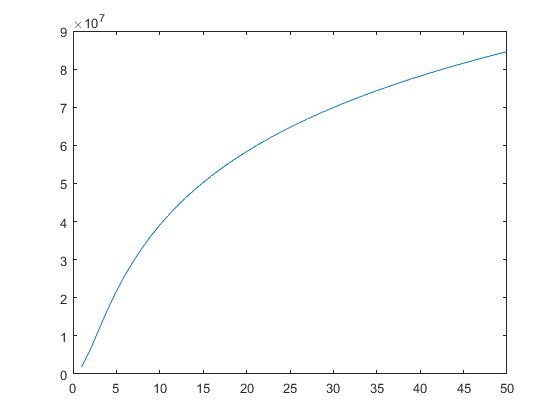

d = zeros(1, 50);
C = zeros(1, 50);
P = 20;
N = 10;
B = 13000000;
F = 2200000000;
c = 300000000;
for index = 1 : 1 : 50
    d(index) = index;
    a = 4 * pi * index * F / c;
    C(index) = B * log2(1 + ( abs(a * a) * P / B * N) );
end

plot(d, C);

Пункт 2. 

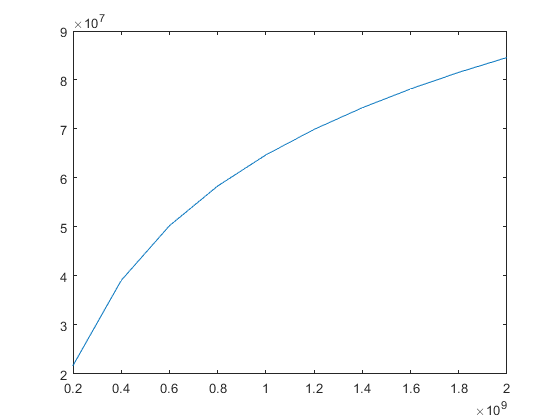

freq = [];
valC = [];
for index = 0.1 * F : 0.1 * F : F
    freq = [freq index];
    a = 4 * pi * 50 * index / c;
    val = B * log2(1 + ( abs(a * a) * P / B * N) );
    valC = [valC val];
end
plot(freq, valC);

Пункт 3. 

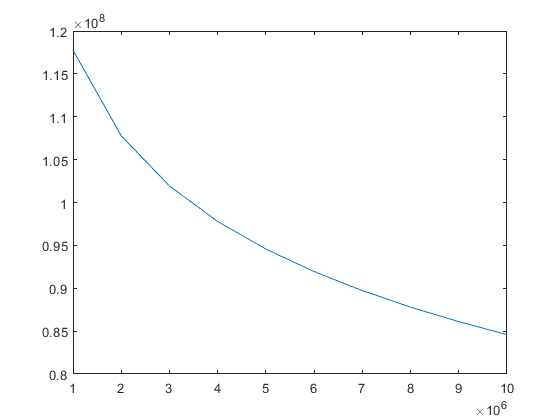

band = [];
valB = [];
for index = 0.1 * B : 0.1 * B : B
    band = [band index];
    a = 4 * pi * 50 * F / c;
    val = B * log2(1 + ( abs(a * a) * P / index * N) );
    valB = [valB val];
end
plot(band, valB);